# EE 451 Homework 2 

# Lisa Jacklin 

# 9/10/2023

## Problem 2. unit step response of the first order IIR Filter. A linear and time invariant discrete system is described by y(n) = 0.5y(n-1) +x(n), y(-1)=0.

### a. find the output using th econvolution relation y(n) = h(n) *x(n) if x(n) = u(n).

n = -5:1:5; %using this range for viewing purposes
ha = (0.5).^n;
hb = stepseq(0,-5, 5);
h = sigadd(ha, n, hb, n); %this gives us h(n) = 0.5^nu(n)

n =     -5    -4    -3    -2    -1     0     1     2     3     4     5


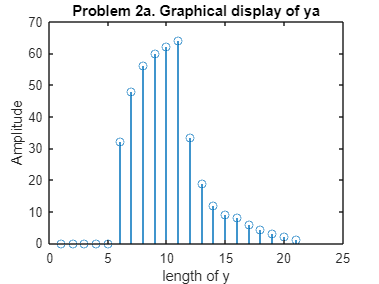


x = stepseq(0, -5, 5); %this gives x(n) = u(n) for the time variation
ya = conv(h, x); %ya = h * x convolution

%and, then to display the output for my own visability.
figure; stem(ya);
title("Problem 2a. Graphical display of ya");
xlabel("length of y"); ylabel("Amplitude");

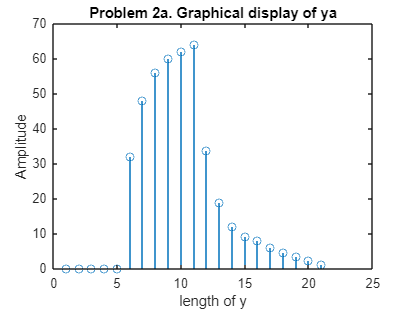

### b. find the output to x(n) = u(n) by solving the difference equation.

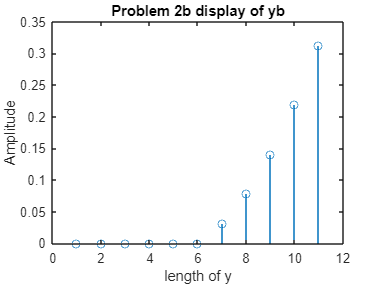

%inorder to display the difference equation, matlab function filter will be
%used.
nb = 0:1:10;
yb = filter(x, h, nb);%note that everything used here comes based from part a.

%and once again, displaying for later comparison and curiosity
figure; stem(yb);
title("Problem 2b display of yb");
xlabel("length of y"); ylabel("Amplitude");

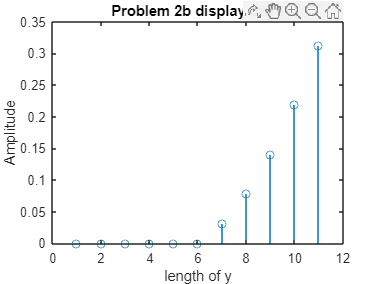

## Problem 3. cacaded system. two LTI systems described by impulse responses h1(n) = delta(n) + delta(n-1) and h2(n) = delta(n) - delta(n-1) are connected in series.

h1a = impseq(0, -5, 5);

x = 1×11 logical array
   0   0   0   0   0   1   0   0   0   0   0


h1b = impseq(1, -5, 5);

x = 1×11 logical array
   0   0   0   0   0   0   1   0   0   0   0


h1 = sigadd(h1a, n, h1b, n);

n =     -5    -4    -3    -2    -1     0     1     2     3     4     5



h2a = impseq(0, -5, 5);

x = 1×11 logical array
   0   0   0   0   0   1   0   0   0   0   0


h2b = impseq(1, -5, 5);

x = 1×11 logical array
   0   0   0   0   0   0   1   0   0   0   0


h2 = sigadd(h2a, n, h2b, n);

n =     -5    -4    -3    -2    -1     0     1     2     3     4     5


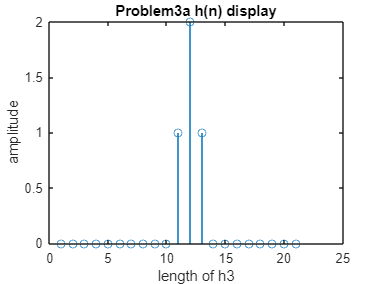


h3 = conv(h2, h1); %resulting h signal

figure; stem(h3);
title("Problem3a h(n) display");
xlabel("length of h3"); ylabel("amplitude");

### b. Is the equivalent system FIR or IIR?

Since h is consistent of several impulse signals, the entire system is finite or FIR.

### c.What is the difference equation described by the system?

### d.Determine the output for the input x(n) = delta(n)+delta(n-1)

%since we already have h based on the convolution in part a, all that needs
%to occur is a adjustment to x(n) which was not used for this problem.

x3a = impseq(0, -5, 5);

x = 1×11 logical array
   0   0   0   0   0   1   0   0   0   0   0


x3b = impseq(1, -5, 5);

x = 1×11 logical array
   0   0   0   0   0   0   1   0   0   0   0


x3 = sigadd(x3a, n, x3b, n); %finished x(n)

n =     -5    -4    -3    -2    -1     0     1     2     3     4     5


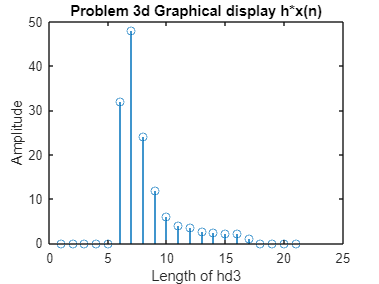


hd3 = conv(x3, h);

figure; stem(hd3);
title("Problem 3d Graphical display h*x(n)");
xlabel("Length of hd3"); ylabel("Amplitude");

## Problem 4.